# 双麦房间各点时延场绘图

%Created time:  2021.09.29
%Author:        beiyi.liu
%Description:   Instantly draw the delay difference when each point in the
%room arrives at the double microphone.

输入房间长宽与麦克风阵列位置（单位：米）

clc;clear all;close all;
roomL = 5;
roomW = 8;
micOneL = 0.1;
micOneW = 4;

roomL = roomL*1000;
roomW = roomW*1000;
roomLengthGrid = 1:roomL;
roomWidthGrid = 1:roomW;

输入麦克风间距（单位：毫米）

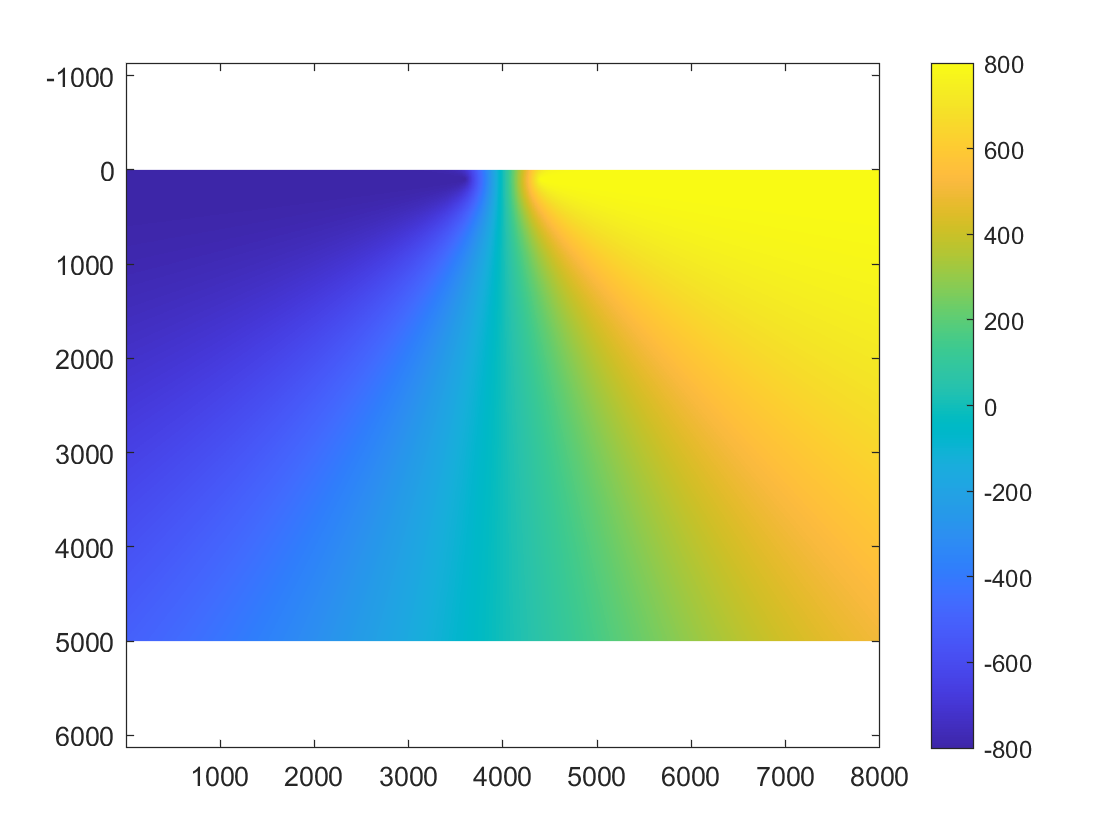

micD = 800;

micPosOne = [micOneL*1000,micOneW*1000-micD/2];
micPosTwo = [micOneL*1000,micOneW*1000+micD/2];

[x,y] = meshgrid(roomLengthGrid,roomWidthGrid);
x = vec(x);
y = vec(y);

pointNum = length(x);

for ii = 1:pointNum
    pointPos = [x(ii),y(ii)];
    rangeDiffVec(ii) = norm(pointPos-micPosOne) - norm(pointPos-micPosTwo);
end
rangeDiffMatx = reshape(rangeDiffVec,roomW,roomL);
imagesc(rangeDiffMatx');colorbar;axis equal;